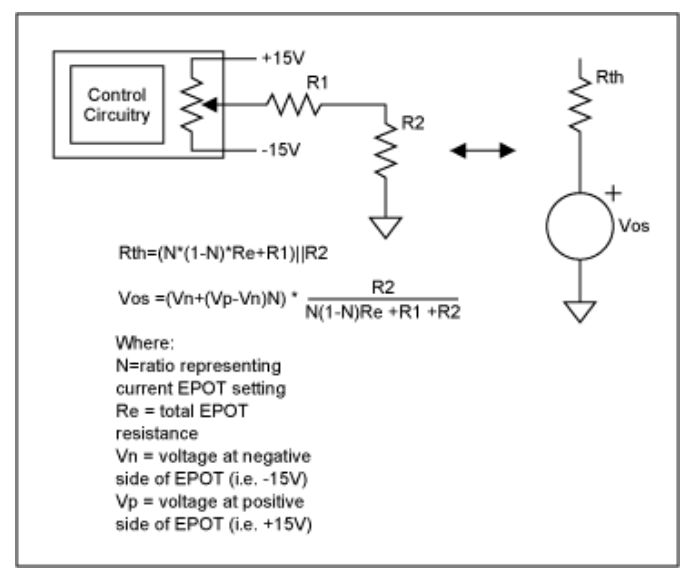

clear
syms Vp Vn N Re R1 R2

Formules voor thevenins weerstand en voltage


$$V_{\mathrm{th}} =\left(V_n +\left(V_p -V_n \right)\cdot N\right)\cdot \frac{R_2 }{N\left(1-N\right)\cdot R_e +R_1 +R_2 }$$



$$R_{\mathrm{th}} =\left(N\cdot \left(1-N\right)\cdot R_e +R_1 \right)\;\|\;R_2$$


Vos = (Vn + (Vp - Vn) * N) * (R2 / (N * (1-N) * Re + R1 + R2))

$$Vos = \frac{R_{2}\,\left(\mathrm{Vn}-N\,\left(\mathrm{Vn}-\mathrm{Vp}\right)\right)}{R_{1}+R_{2}-N\,\Re\,\left(N-1\right)}$$

Vos = subs(Vos, {Vp, Vn, Re, R1, R2}, {15, -15, 100e3, 10e3, 10e3});

Rt = (N * (1-N) * Re + R1)

$$Rt = R_{1}-N\,\Re\,\left(N-1\right)$$

Rth = (Rt * R2) / (Rt + R2)

$$Rth = \frac{R_{2}\,\left(R_{1}-N\,\Re\,\left(N-1\right)\right)}{R_{1}+R_{2}-N\,\Re\,\left(N-1\right)}$$

Rth = subs(Rth, {R1, R2, Re}, {10e3, 10e3, 100e3});

Plot the formulas over the full range of the trim pot

range = linspace(0, 1, 100);
Vos = subs(Vos, N, range);
Rth = subs(Rth, N, range);

Plots

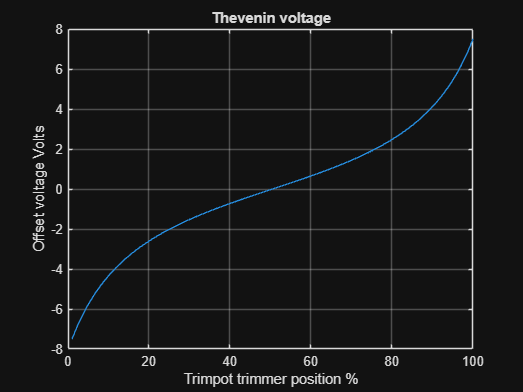

figure;
plot(Vos);
title("Thevenin voltage");
xlabel("Trimpot trimmer position %")
ylabel("Offset voltage Volts");
grid on;

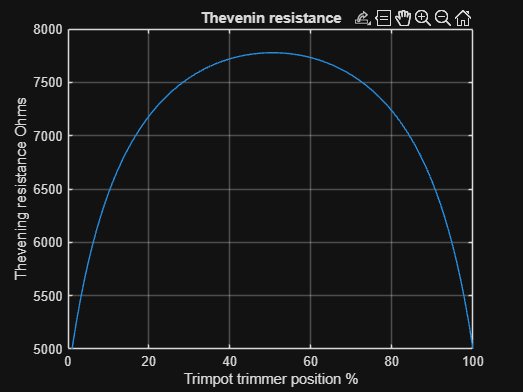


figure;
plot(Rth);
title("Thevenin resistance");
xlabel("Trimpot trimmer position %")
ylabel("Thevening resistance Ohms");
grid on;